# Homework #6. Due 11:59PM (EST), Tuesday, April 13

## Problem 1 (20 points)

As part of your internship for a car manufacturer safety lab, you collect the data below on the car stopping distance (*SD*) as a function of its traveling speed (*V*). You plan to use this data to validate the model 

                                                    $SD=\frac{V^2}{2\mu g}+VT$, 

where $\mu$ is the coefficient of friction between the tires and the road surface, $g=9.81m/s^2$ is the acceleration due to gravity and $T$ is the driver reaction time (in seconds).

a) (15 points) Use a least-squares analysis to see if your model fits the data given below well and determine least-square estimates for $T$ (`T` in Matlab) and $\mu$ (`mu` in Matlab).  Plot your model on the graph below using a black solid line; use `linspace` to generate 30 points in the interval $50\leq V\leq  200$ for the latter plot.

V=[50 80 120 160 200]'; %in Km/h
SD=[20 46 80 155 220]'; % in m
plot(V,SD,'bo')
xlabel('velocity [Km/h]')
ylabel('stopping distance [m]')
% Put your code below
hold on
X = [V V.^2]; % Form the augmented matrix of data
[Q,R] = qr(X,0);   % Compute the QR decomposition of X
B_hat = R \ (Q'* SD);  % Compute the parameters of the regression eqn
g = 9.81;
T = B_hat(1)

T = 0.1604

mu = 1/(B_hat(2)*2*g) %1/(2*mu*g) = B_hat(2)

mu = 10.7097

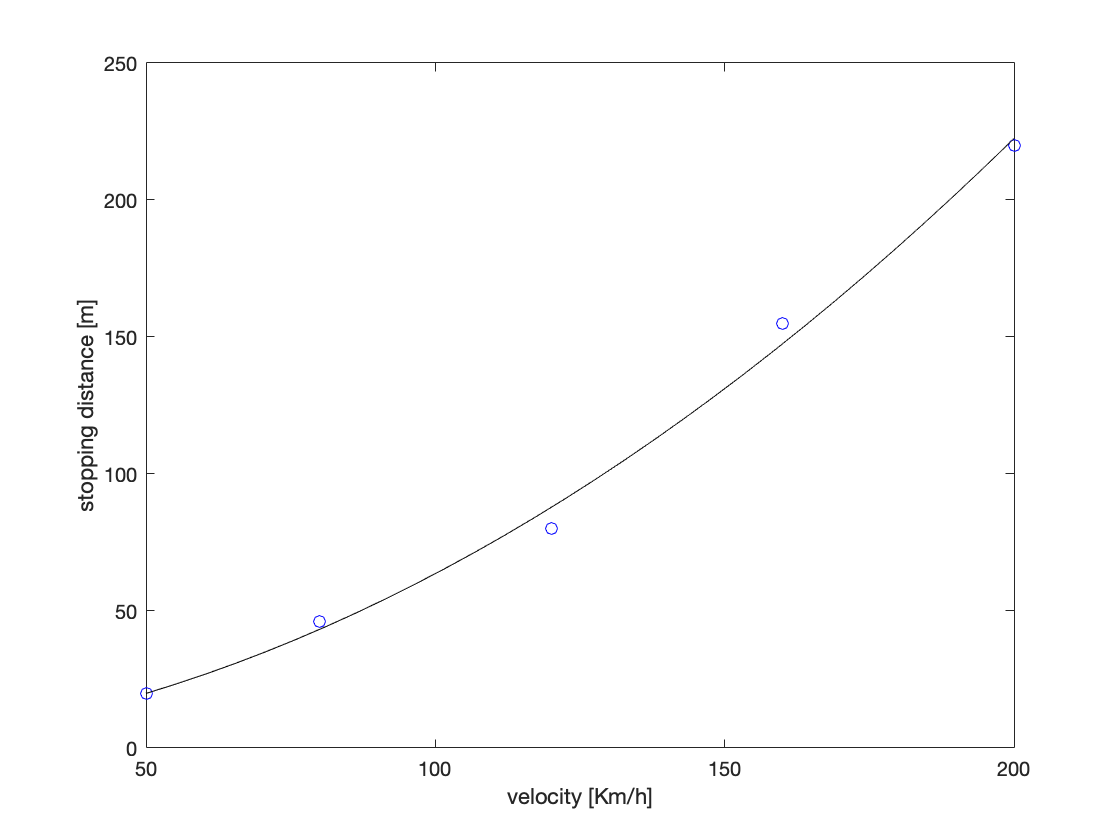

V2 = linspace(50,200,30)';
X2 = [V2 V2.^2];
SD_hat2= X2*B_hat;
plot(V2,SD_hat2,'k-')
hold off;

b) (5 points) Make a plot of $SD-\hat{SD}$ as as function of $V$, where $\hat{SD}$ is the model prediction for the stopping distance. $\hat{SD}$ should be calculated using the "design matrix" $X$and the vector of fitted coefficients $\beta$.

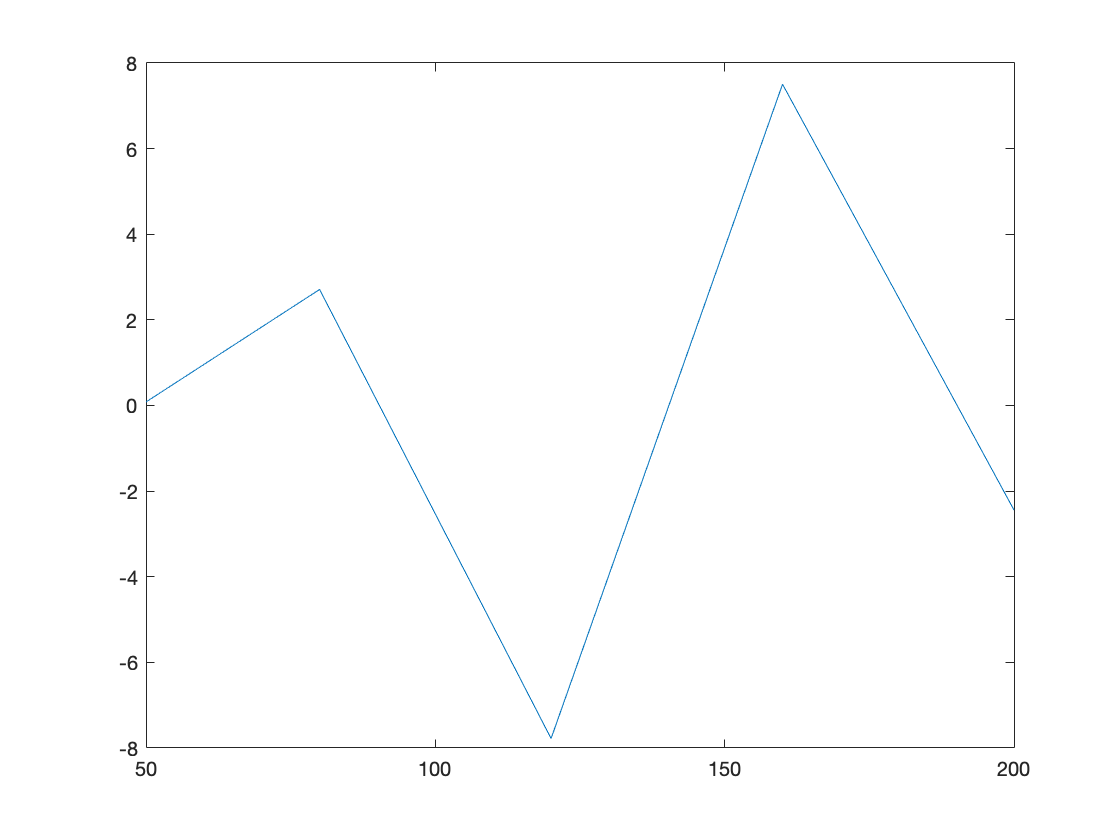

% Put your code below
SD_hat = X*B_hat;
plot(V,SD-SD_hat)

## Problem 2 (15 points)

Imagine that you collect the following experimental data, which is supposed to be fit by the function $P=a\exp(cx)$, where $a$ and $c$ are constants

clear
clf
x=[1.2 2.9 4.3 5.4 6.8 8]';
P=[7.5 16 39 67 147 266]';
figure
plot(x,P,'bo')

Use a least squares fitting process to determine the two constants $a$ and $c$. Plot the resulting fit on the same figure using a red solid line; use` linspace` to generate 40 points in the interval $1\leq x\leq  8$ for this plot. Label your plot accordingly.

% Put your work here
%fitting to lnP = lna + cx
X = [ones(size(x,1),1) x]; % Form the augmented matrix of data
[Q,R] = qr(X,0);   % Compute the QR decomposition of X
B_hat = R \ (Q'* log(P))  % Compute the parameters of the regression eqn

B_hat =     1.3236
    0.5345


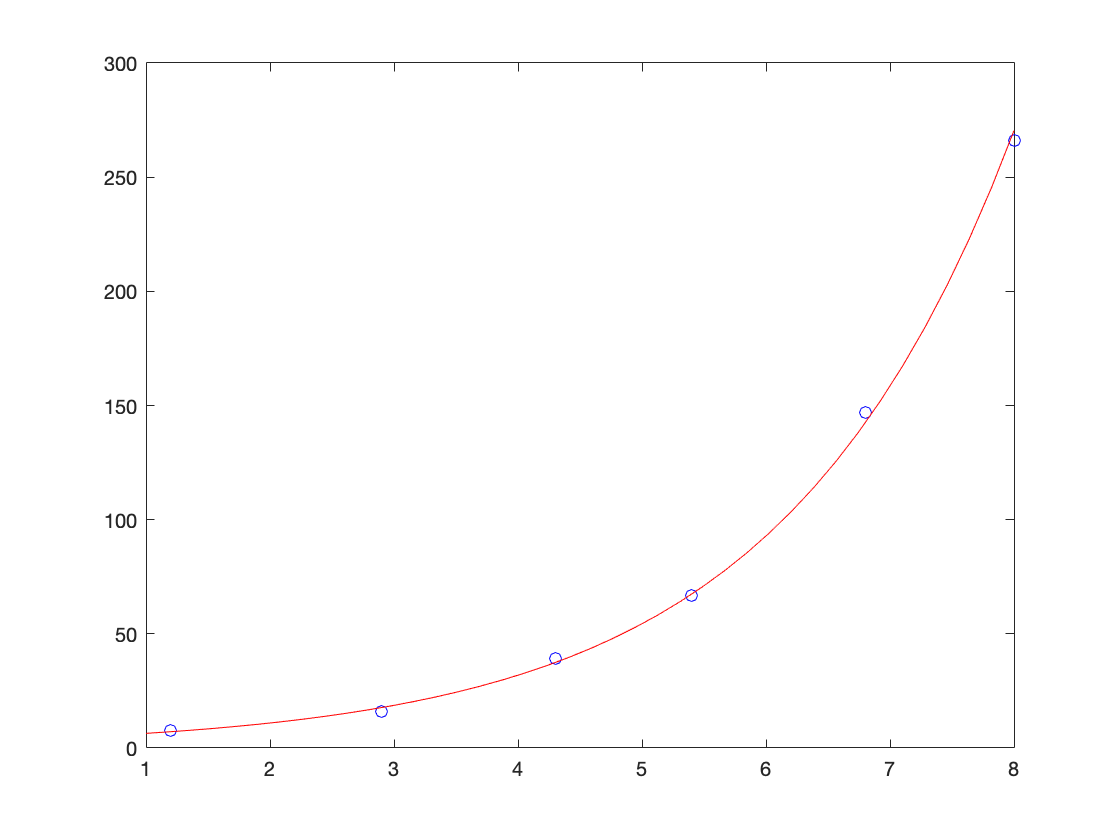

%b0=lna, b1=c
a = exp(B_hat(1));
c = B_hat(2);
x2 = linspace(1,8,40)';
P_hat = a*exp(c*x2);
hold on
plot(x2,P_hat,'r-');
hold off

## Problem 3 (25 points)

The data below were extracted from Ref. [1]. The data shows the fuel consumption (*F*), in the units of tons/day, of a ship as a function of its traveling speed (*S*), in the units of knots:

[[1]](https://www.sciencedirect.com/science/article/pii/S2468013315300127) Bialystocki, N. and D. Konovessis, 2016,  "On the estimation of ship’s fuel consumption and speed curve: A statistical approach" *Journal of Ocean Engineering and Science* vol. 1**, **pp. 157–166.

% Below is a reasonable representation of the data that we extracted from an image in the paper
clear
speed=[18.425,19.45,19.91875,19.275,19.1625,19.09375,18.925,18.23125,17.15625,17.7875,17.675,...
         18.46875,17.5125,17.30625,17.1,16.5625,17.86875,16.825,17.35,16.75,17.5625,16.9,16.31875,...
         15.23125,16.1125,16.25,14.6125,15.0375,14.825,15.63125,15.58125,16.09375,15.525,15.83125,...
         15.45,15.76875,15.375,15.30625,15.2,15.1125,15.575,15.05625,15.4375,14.95625,15.925,14.8,...
         14.70625,15.54375]';
fuel=[67.9287,66.2229,66.2229,66.1011,64.1517,63.786,63.0551,58.3034,55.9885,53.4298,52.5770,...
        51.9678,51.3586,50.7494,49.409,49.0436,48.8,46.4850,46.4850,45.9977,45.8758,43.4390,43.195,...
       	42.9517,42.829,42.7080,41.3678,41.367,40.1494,38.4436,38.2,37.8344,37.7126,37.468,37.3471,...
       	37.1034,36.8597,36.25,35.7632,35.5195,35.2758,34.9103,34.4229,34.1793,34.1793,33.5701,32.8390,31.133]';


a) (2 points) Plot the fuel consumption as a function of speed using asterisk symbols (*). Label your figure appropriately.

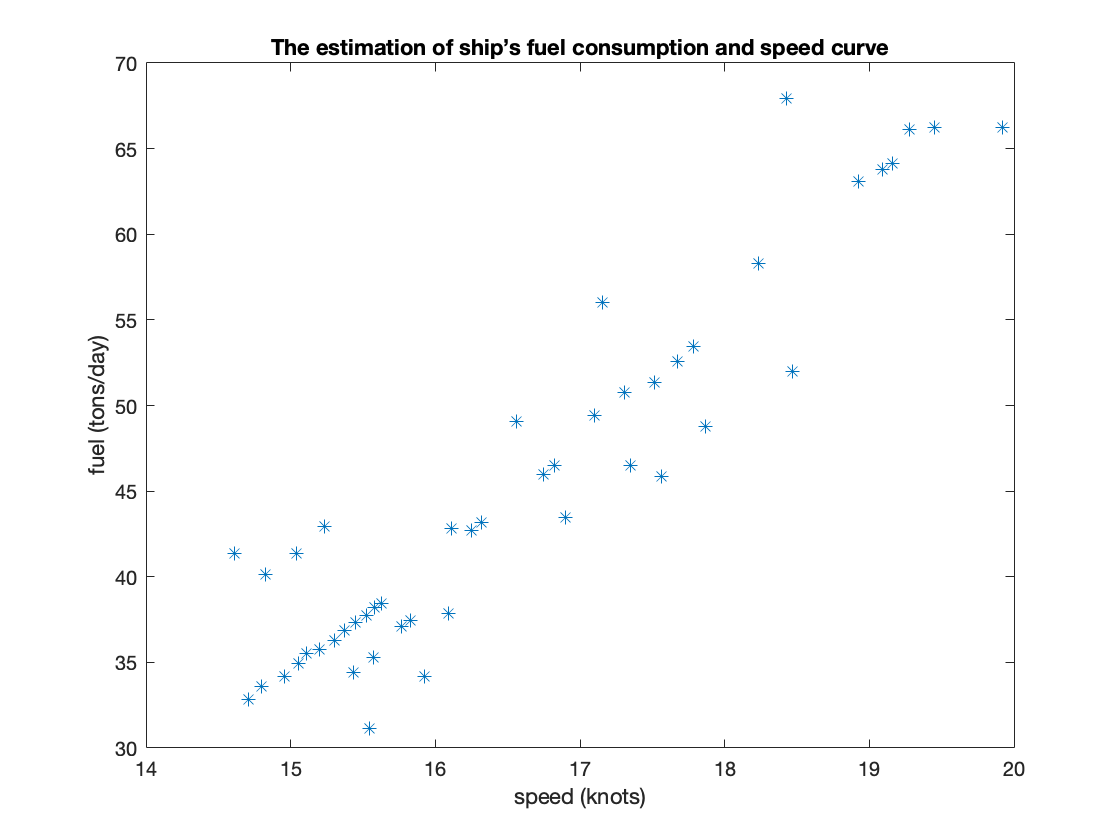

% Put your work below
plot(speed,fuel,'*')
title("The estimation of ship’s fuel consumption and speed curve")
xlabel("speed (knots)")
ylabel("fuel (tons/day)")

b) (6 points) From the plot, it appears that the simplest fit to the data is of the form `F=beta_0+beta_1*S`. Create a MATLAB script that calculates the best fit coefficients (in a least squares sense) `beta_0 and` `beta_1` and save them as `beta_L_0 and` `beta_L_1.` Here you can assume your model is only going to be used for predictions for 14<*S*<20. Superimpose your model onto the actual data on a new plot. Plot your results in the range 14<*S*<20.  Label your figure appropriately. Calculate the sum squared error as a measure of the goodness of fit and save it in the variable J_L.

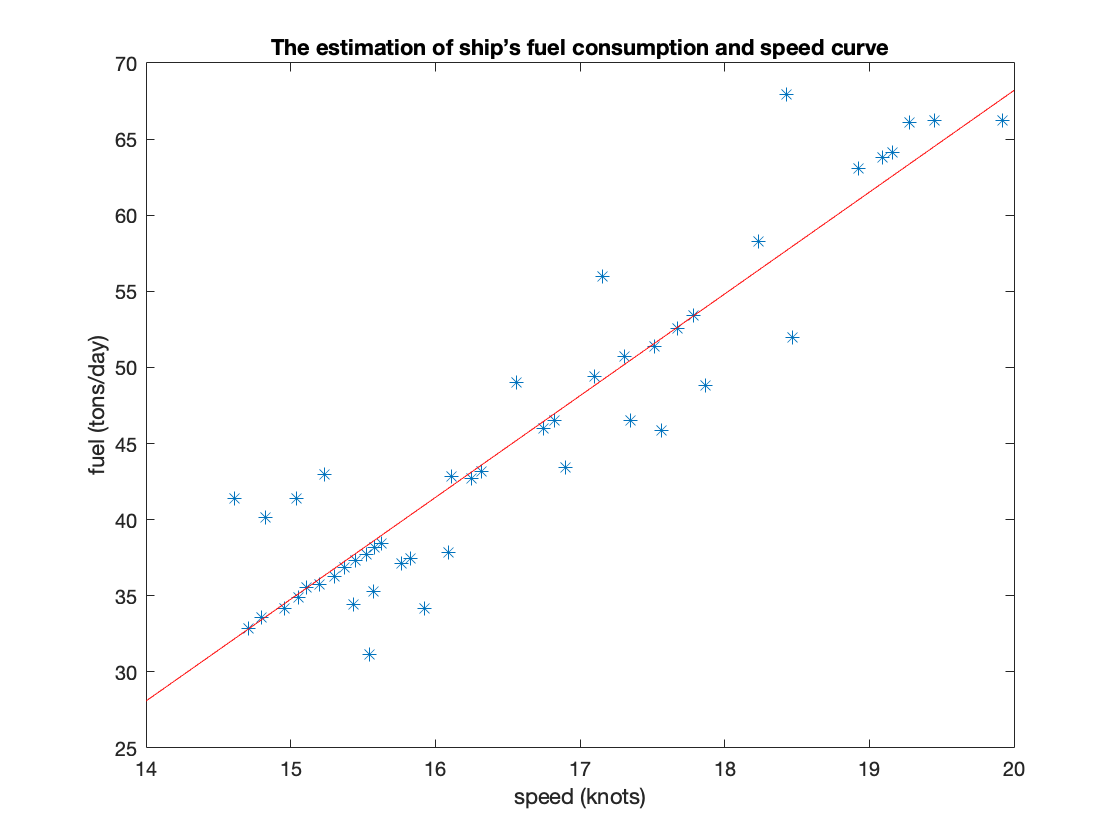

% Put your work here
hold on
X=[ones(size(speed,1),1) speed];  % Form a model matrix
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* fuel); % Compute the parameters of the regression eqn
fuel_hat= X*B_hat;
speed2 = linspace(14,20)';
X2=[ones(size(speed2,1),1) speed2];
fuel_hat2= X2*B_hat;  % Compute the "predicted" values of wear
plot(speed2,fuel_hat2,'r-')

J_L = sum(norm(fuel_hat-fuel).^2)

J_L = 692.7792

c) (7 points) As an engineer you wonder whether a linear model is too simple (after all, even if the drag opposing the ship motion is linear with the speed, the power needed, which is proportional to the fuel flow rate, would be quadratic). Create a MATLAB script that calculates the best fit coefficients (in a least squares sense) `beta_0`, `beta_1`, `and` `beta_2` for a quadratic model of the form `F=beta_0+beta_1*S+beta_2*S^2` and save them as `beta_Q_0`, `beta_Q_1 and` `beta_Q_2`. Here you can assume your model is only going to be used for predictions for 14<*S*<20. Superimpose your model onto the actual data on a new plot. Plot your model in the range 14<*S*<20.  Calculate the sum squared error as a measure of the goodness of fit and save it in the variable J_Q. Is this fit any better than the one you created in part (b)?

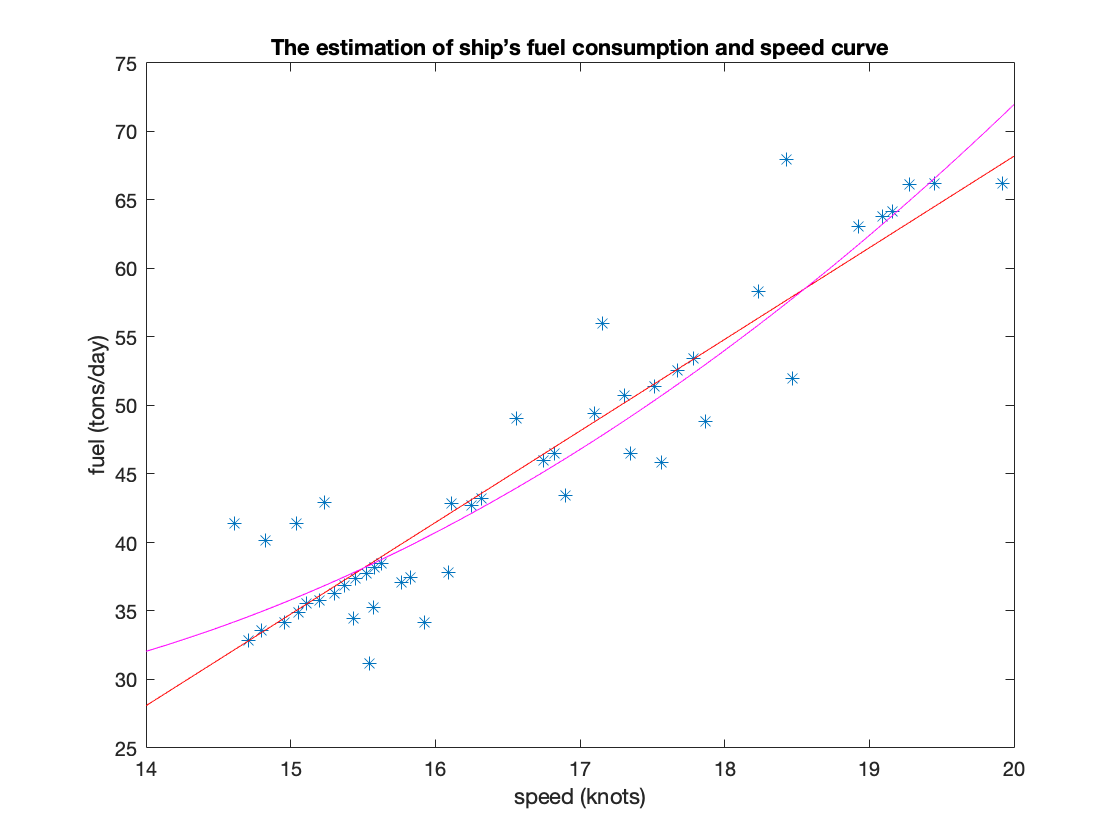

% Put your work here
hold on
X=[ones(size(speed,1),1) speed speed.^2];  % Form a model matrix
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* fuel); % Compute the parameters of the regression eqn
fuel_hat= X*B_hat;
X2=[ones(size(speed2,1),1) speed2 speed2.^2];
fuel_hat2= X2*B_hat;  % Compute the "predicted" values of wear
plot(speed2,fuel_hat2,'m-')

J_Q = sum(norm(fuel_hat-fuel).^2)

J_Q = 629.5374

% write your comment here
% Yes, but not so much better as J_L = 692.7792 and J_Q = 629.5374. I
% believe this is an example of overfitting - the data shows a linear
% pattern and applying a polynomial regression will not be a good model.

d) (7 points) If the drag is quadratic in speed, the fuel flow would be cubic in *S*. Create a MATLAB script that calculates the best fit coefficients (in a least squares sense) `beta_0`, `beta_1`, `beta_2`, and `beta_3` for a cubic model of the form `F=beta_0+beta_1*S+beta_2*S^2+beta_3*S^3` and save them in  `beta_C_0`, `beta_C_1`, `beta_C_2 and beta_C_3`. Here you can assume your model is only going to be used for predictions for 14<*S*<20. Superimpose your model onto the actual data in a new plot. Plot your model in the range 14<*S*<20. Calculate the sum squared error as a measure of the goodness of fit and save it in the variable J_C.  Is this fit any better than the ones you created in parts (b) and (c)?

% Put your work here 
hold on
X=[ones(size(speed,1),1) speed speed.^2 speed.^3];  % Form a model matrix
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* fuel); % Compute the parameters of the regression eqn
fuel_hat= X*B_hat;
X2=[ones(size(speed2,1),1) speed2 speed2.^2 speed2.^3];
fuel_hat2= X2*B_hat;  % Compute the "predicted" values of wear
plot(speed2,fuel_hat2,'g-')
hold off
J_C = sum(norm(fuel_hat-fuel).^2)

J_C = 551.1981

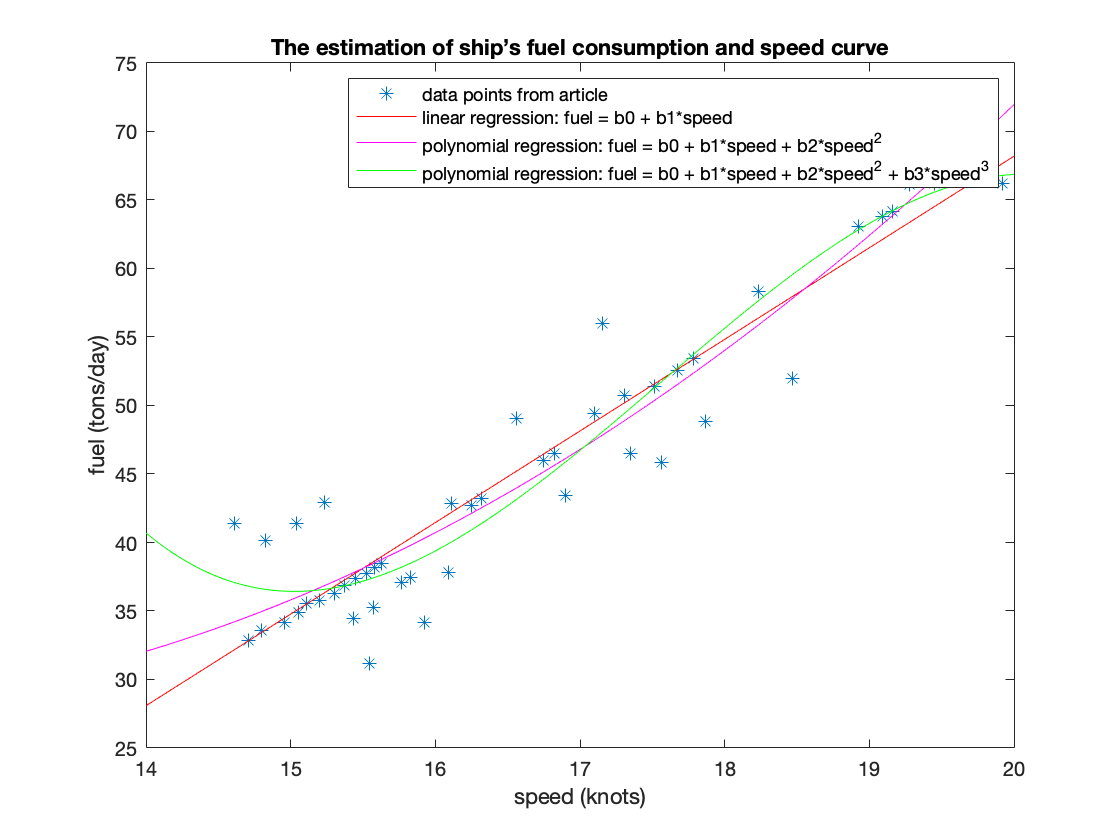

legend("data points from article","linear regression: fuel = b0 + b1*speed","polynomial regression: fuel = b0 + b1*speed + b2*speed^2","polynomial regression: fuel = b0 + b1*speed + b2*speed^2 + b3*speed^3")

% write your comment below
% while J_Q is significatly smaller than J_L and J_Q, it is an example of overfitting.
% looking at the ends around speed=14 and speed=20, one can see that the
% curve does not follow the data point's patterns well.

e) (3 points) Discuss your results. Here we expect both qualitative (looking at the plots) but also quantitative discussion (based on goodness of fit associated with each fit). Is goodness of fit by itself a good measure of the quality of the fit? 

% Put your comment here
% Goodness of fit is not the best measure of the quality of the fit on its
% own as adding coefficients to the inherently yields a smaller sum squared
% error even if it does not reflect the pattern on the data well. It can,
% however, be a good point of reference when used alongside other fit
% quality measurements.

## Problem 4 (20 points)

The data $\theta=\theta(V)$given below are expected to be fitted by the relation $\cos(\theta)=\cos(\theta_0)+A\sinh^{-1}(B V)$, where $\theta_0$, $A$ and $B$ are fitting constants and $\sinh^{-1}$ is the arcsinh function (`asinh` in Matlab). 

clear
figure
V=[0.5 2 4 7 10 12 14]';
theta=[15.9 30.9 53.5 72.2 77.2 90 97.7]'*pi/180;
plot(V,cos(theta),'ro')
xlabel('V')
ylabel('cos(theta)')

a) (2 points) Can you use least squares to fit this data and determine the coefficients  $\theta_0$, $A$ and $B$ ? Explain your answer.

% Put your answer here
% no, since there is no way to isolate the A and B coefficients to create
% an equation where thetavec = xvec * betavec

b) (13 points) Use the Matlab non-linear least-squares fitting function `lsqcurvefit `to fit the data and determine the coefficients  $\theta_0$, $A$ and $B$. The usage for  this function can be found under` docs lsqcurvefit.`

% Put your work here
% coeffs = theta0, A, B
fun = @(coeffs,V) cos(coeffs(1)) + coeffs(2)*asinh(coeffs(3)*V);
start = [2, -0.5, 1]; %copied from piazza
coeffs = lsqcurvefit(fun,start,V,cos(theta));


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


cos_theta_hat = fun(coeffs,V);
theta_0 = coeffs(1)

theta_0 = 6.6876e-04

A = coeffs(2)

A = 0.8805

B = coeffs(3)

B = -0.1143

c) (5 points)  Plot your non-linear fit on  the above figure using a black solid line.

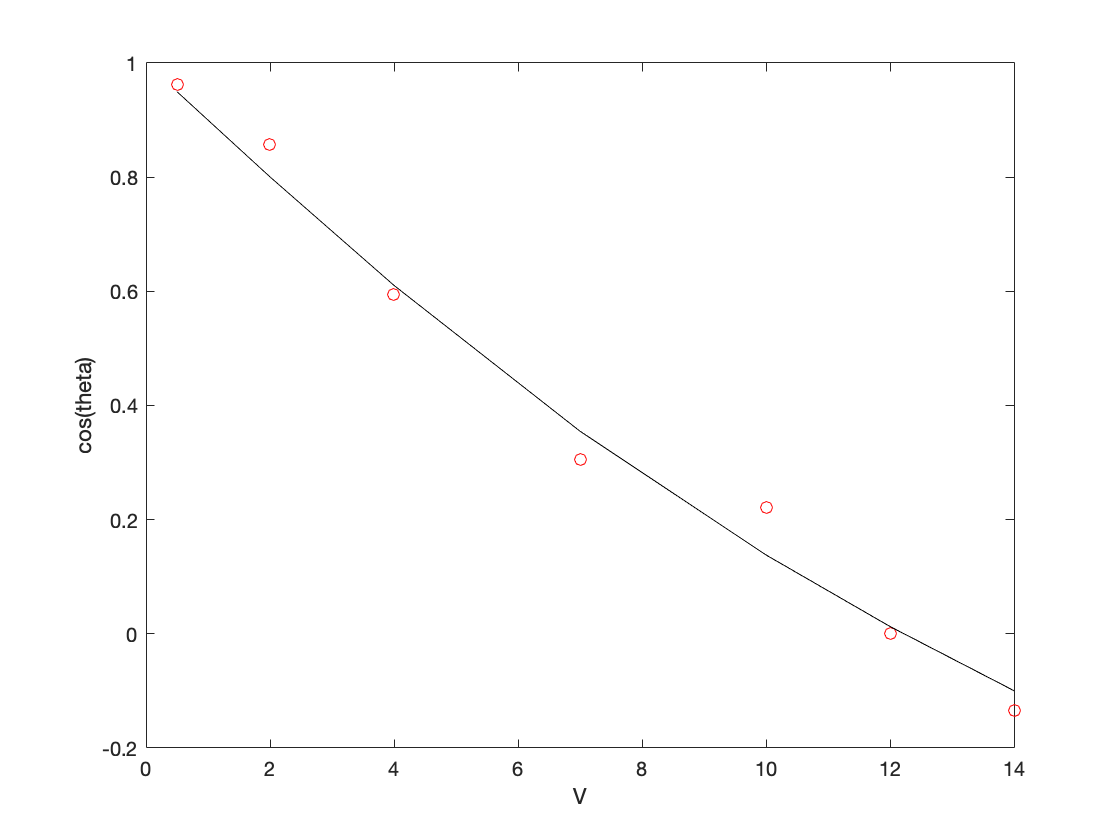

% Put your work here
hold on 
plot(V,cos_theta_hat,"k-")

## Problem 5 (20 points)

The theory and experience of ship making tells us that neither a linear nor a quadratic relationship is likely to be sufficient for describing ship resistance if you have a large quantity of precise measurements over a wide range of speeds.  For example, the textbook on propulsion of ships used at the U.S. Naval Academy shows that total resistance experienced by a ship appears to include an upward curving region at low speeds, a plateau at intermediate speeds, and a steeply upward curving region at high speeds.  The location of the plateau in the resistance curve is dependent on the length of the hull.  

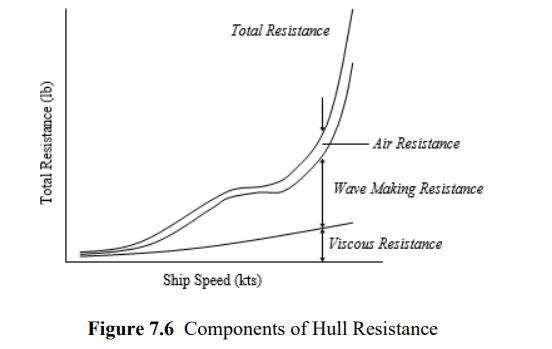

This figure above is from: [Chapter 7 Resistance and Powering of Ships (usna.edu)](https://www.usna.edu/NAOE/_files/documents/Courses/EN400/02.07%20Chapter%207.pdf)

The code below plots 1000 data points for a ship model weighing 500 pounds known as "model 892".  The plot shows total hull resistance over a range of speeds and lengths:

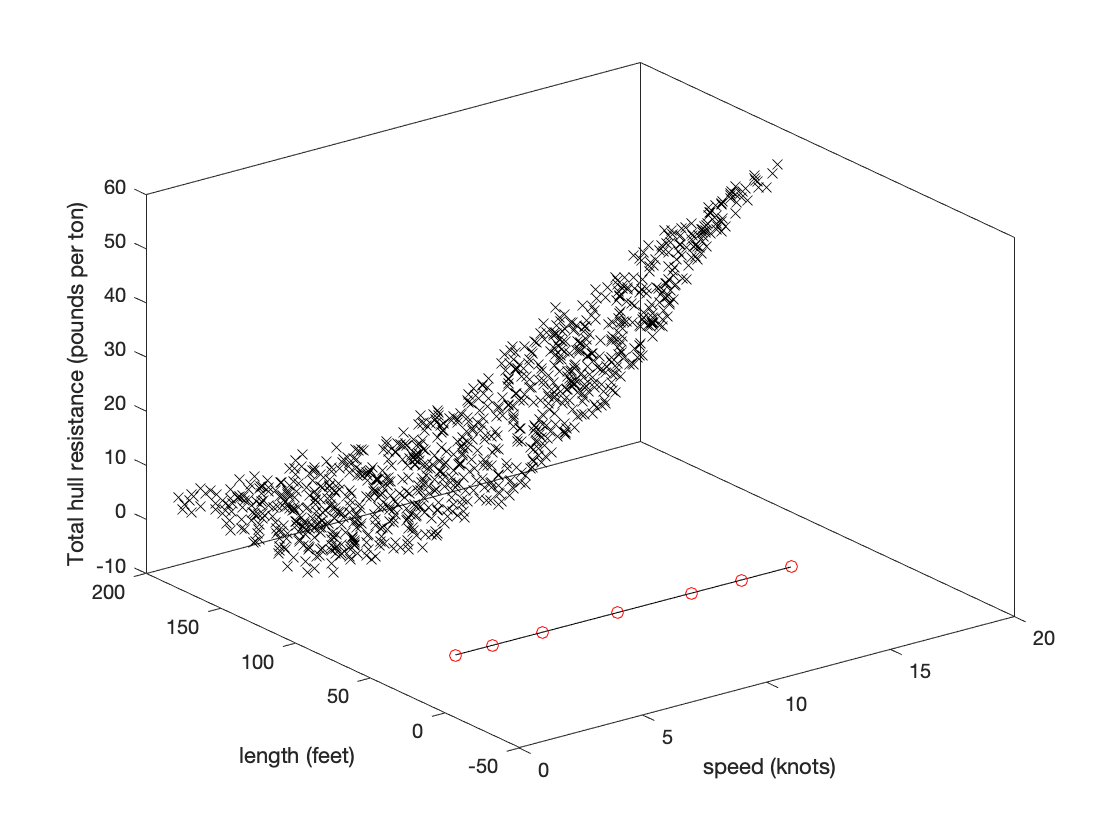

% Create a set of sample independent variables
% You can imagine that these are the values from an experiement
HullSpeed=1+rand(1000,1)*19; % Randomly spreading the speeds from 1 to 20 knots
HullLength=100+rand(1000,1)*100; % Randomly spreading the lengths from 100 to 200 feet
for i=1:length(HullSpeed)
     HullResistance(i)=DragFunct(HullLength(i),HullSpeed(i));
end
figure(2)
plot3(HullSpeed,HullLength,HullResistance,'kx')
zlabel('Total hull resistance (pounds per ton)')
xlabel('speed (knots)')
ylabel('length (feet)')
view(-37,30)

Consider the models for total hull resistance as a function of speed V and length L with linear combinations of terms of the form $\beta_i V^p L^q$ where $p=\left\lbrace 0,1,2,3\right\rbrace$ and $q=\left\lbrace -3,-2,-1,0,1\right\rbrace$.  

a) (14 points) There are 20 possible coefficients, but you should consider only models with exactly five terms and you should always include the constant term $p=0$ $q=0$ .   Among those models, compute the "coefficient of determination" (also known as "Regression $R^2$") for each model and store them in a vector called R2.

% Your code here
% beta is size 5 where beta = [b0, b1, b2, b3, b4, b5] where b0 is always
% for the constant term
p0 = ones(length(HullSpeed),1);
p1 = HullSpeed;
p2 = HullSpeed.^2;
p3 = HullSpeed.^3;
qn3 = HullLength.^(-3);
qn2 = HullLength.^(-2);
qn1 = HullLength.^(-1);
q0 = ones(length(HullLength),1);
q1 = HullLength;
p_vals = [p0 p1 p2 p3];
q_vals = [qn3 qn2 qn1 q0 q1];

p = [0,1,2,3];
q = [-3,-2,-1,0,1];
possible_coeffs = ones(19,2); %not including p0q0
n=0;
Y_bar = mean(HullResistance);
for i = 1:length(p)
    for j = 1:length(q)
        if p(i)==0 && q(j)==0
            continue
        else
            n=n+1;
            possible_coeffs(n,:) = [p(i), q(j)];
        end
    end
end
index_combos_wo_zeros = combnk(1:n,4); %size 4 combos of the row#s in possible_coeffs (not including index for p0q0=zero_zero_index)
R2 = [];
for isize4combo = 1:length(index_combos_wo_zeros) %for index of size4combo in index_combos_wo_zeros
    %size4combo is array of rows in possible_coeffs
    size4combo = index_combos_wo_zeros(isize4combo,:);
    coeff_combo = [];
    for i = 1:length(size4combo)
        coeff_combo(i,:) = possible_coeffs(size4combo(i),:);
    end
    coeff_combo(i+1,:) = [0 0]; %adding the p0q0 coefficient
    %coeff_combo is now a 5*2 array
    X = [];
    for i = 1:length(coeff_combo)
        p_val = coeff_combo(i,1);
        pV = p_vals(:,p_val+1);
        q_val = coeff_combo(i,2);
        qL = q_vals(:,q_val+4);
        X(:,i) = pV.*qL;
    end
    [Q,R] = qr(X,0); % Compute the QR decomposition of X
    B_hat = R \ (Q'* HullResistance'); % Compute the parameters of the regression eqn
    HullResistance_hat= X*B_hat;
    R2(isize4combo)=1-sum(((HullResistance_hat)-HullResistance').^2)/sum((HullResistance'-mean(HullResistance)).^2);  % Compute R^2
end

b) (6 points) Select the model with the highest coefficient of determination ("Regression $R^2$") and plot the model's predictions of "Total Hull Resistance" versus hull speed (ranging from 1 to 20 knots) and hull length (ranging from 100 to 200 feet).  Please make the model predictions appear in the same 3D plot alongside the data so that you can visually assess the fit.    

% Your code here
max(R2)

ans = 0.9879

hR2_index = find(R2==max(R2));
hR2_size4combo = index_combos_wo_zeros(hR2_index,:);
hR2_coeff_combo = [];
for i = 1:length(hR2_size4combo)
    hR2_coeff_combo(i,:) = possible_coeffs(hR2_size4combo(i),:);
end
hR2_coeff_combo(i+1,:) = [0 0];
for i = 1:length(hR2_coeff_combo)
        p_val = hR2_coeff_combo(i,1);
        pV = p_vals(:,p_val+1);
        q_val = hR2_coeff_combo(i,2);
        qL = q_vals(:,q_val+4);
        X(:,i) = pV.*qL;
end
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* HullResistance'); % Compute the parameters of the regression eqn

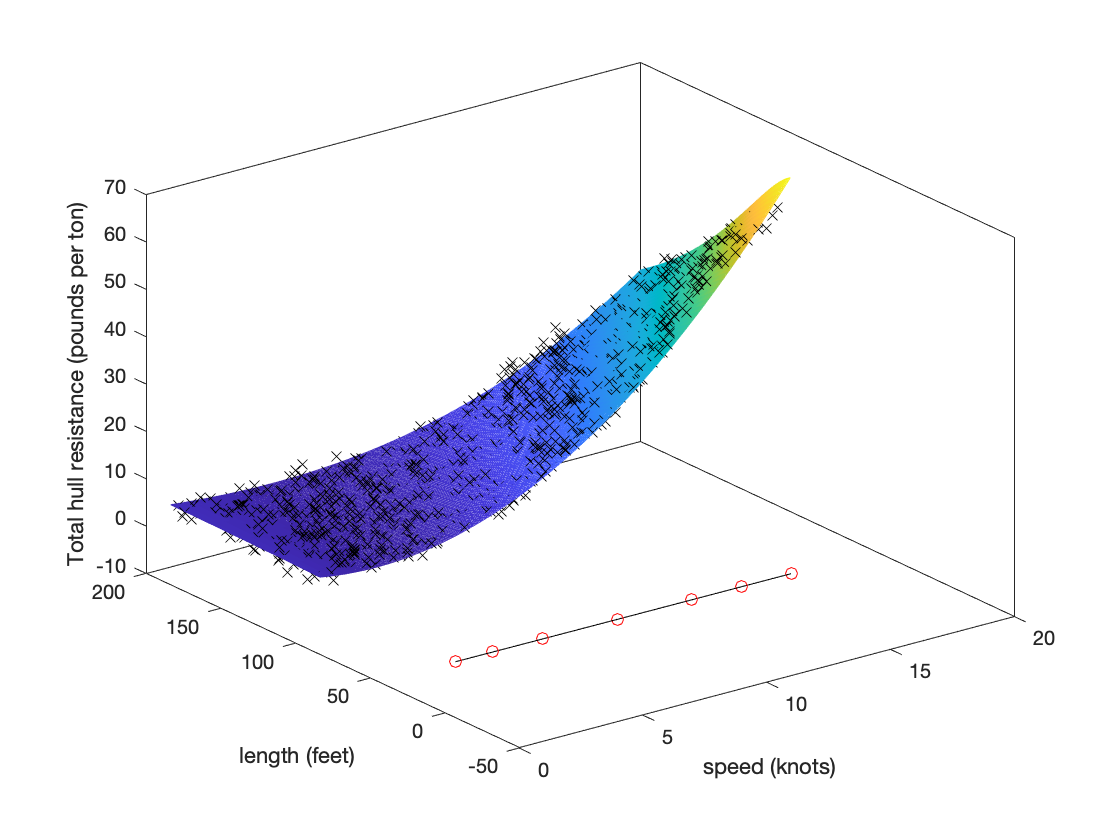

HS = linspace(1,20)';
HL = linspace(100,200)';
[HSgrid HLgrid] = meshgrid(HS,HL);
p0 = ones(length(HS),1);
p1 = HS;
p2 = HS.^2;
p3 = HS.^3;
qn3 = HL.^(-3);
qn2 = HL.^(-2);
qn1 = HL.^(-1);
q0 = ones(length(HL),1);
q1 = HL;
p_vals = [p0 p1 p2 p3];
q_vals = [qn3 qn2 qn1 q0 q1];
hr_func = @(HS, HL) B_hat(1)*(HS.^(hR2_coeff_combo(1,1))).*(HL.^(hR2_coeff_combo(1,2)))+B_hat(2)*(HS.^(hR2_coeff_combo(2,1))).*(HL.^(hR2_coeff_combo(2,2)))+B_hat(3)*(HS.^(hR2_coeff_combo(3,1))).*(HL.^(hR2_coeff_combo(3,2)))+B_hat(4)*(HS.^(hR2_coeff_combo(4,1))).*(HL.^(hR2_coeff_combo(4,2)))+B_hat(5)*(HS.^(hR2_coeff_combo(5,1))).*(HL.^(hR2_coeff_combo(5,2)));
hold on
mesh(HSgrid, HLgrid, hr_func(HSgrid, HLgrid))

function Drag = DragFunct(Length, shipSpeed)
c=shipSpeed/sqrt(Length); % Parameter from the empirical formula similar to a Froude number
alpha=2; % Parameter from an empirical fit to data controlling the size of the first term
beta=87; % Parameter from an empirical fit to data controlling the size of the second term
gamma=0.14; % Parameter from an empirical fit to data controlling the amplitude of a dip in the drag curve
cp=1.3; % Parameter from an empirical fit to data controlling the location of a dip in the drag curve
Drag=2+alpha*exp(-2.53/(9*c^2))+beta*(1-gamma*cos(10.2/c^2))*exp(-1.5*(cp/c)^2)+randn(1,1);
end

This formula was adapted from:

https://royalsocietypublishing.org/doi/pdf/10.1098/rspa.1909.0033